clear; clc;
Path = fullfile('..', 'DVDPL', 'Data');
Plot_Path = '.';

## 1. 数据读取与方法加载

load(fullfile(Path, 'Data_Train_DeLAN_end_250s.mat')); Train = data;
load(fullfile(Path, 'Data_Test_draw8_96s.mat')); Test = data;
Test_real = Test.Ff;

methods_name = {'FFN', 'DeLaN', 'CAD', 'SID', 'VDCDL-Fixed', 'VDCDL-NoCADPrior', 'VDCDL'};

% 1.1 FFN (750s, 5 个随机种子)
ffn_seeds = {'42', '518772', '942385', '607344', '149710'};
for k = 1:5
    FFN.pred{k} = readmatrix(fullfile(Plot_Path, sprintf('FFN_Test3_96s_%s.xlsx', ffn_seeds{k})));
end

% 1.2 DeLaN (750s, 5 个随机种子)
delan_seeds = {'43528', '246957', '783196', '760674', '31356'};
for k = 1:5
    DeLaN.pred{k} = readmatrix(fullfile(Plot_Path, sprintf('DeLaN_Test3_96s_%s.xlsx', delan_seeds{k})));
end

% 1.3 CAD (名义参数)
temp = load(fullfile(Plot_Path, 'CAD_Test_96s.mat'));
CAD.pred = temp.F_CAD;

% 1.4 SID (750s LSQ辨识)
temp = load(fullfile(Plot_Path, 'LSQ_Test2_96s.mat'));
SID.pred = temp.Fpre;

% 1.5 VDCDL-Fixed (消融 1, 250s, 5 个随机种子)
vdcdl_seeds = {'78963', '103809', '483628', '699028', '743384'};
for k = 1:5
    VDCDL_Fixed.pred{k} = readmatrix(fullfile(Plot_Path, sprintf('VDCDL_Test3_96s_fixed_%s.xlsx', vdcdl_seeds{k})));
end

% 1.6 VDCDL-NoCADPrior (消融 2, 250s, 5 个随机种子)
for k = 1:5
    VDCDL_NoCADPrior.pred{k} = readmatrix(fullfile(Plot_Path, sprintf('NoCADPrior_Test3_96s_%s.xlsx', vdcdl_seeds{k})));
end

% 1.7 VDCDL (完整方法, 250s, 5 个随机种子)
for k = 1:5
    VDCDL.pred{k} = readmatrix(fullfile(Plot_Path, sprintf('VDCDL_Test3_96s_%s.xlsx', vdcdl_seeds{k})));
end

% 注: CAD_Fri (CAD-F) 已根据最新实验方案去除
clear temp data;

## 2. 统一误差计算 (各关节 MAE / RMSE，5 种子独立计算后求 Mean ± Std)

% 2.1 学习方法 (5 个独立种子统计)
FFN_MAE_j = zeros(5, 3); FFN_RMSE_j = zeros(5, 3);
DeLaN_MAE_j = zeros(5, 3); DeLaN_RMSE_j = zeros(5, 3);
VDCDL_Fixed_MAE_j = zeros(5, 3); VDCDL_Fixed_RMSE_j = zeros(5, 3);
VDCDL_NoCADPrior_MAE_j = zeros(5, 3); VDCDL_NoCADPrior_RMSE_j = zeros(5, 3);
VDCDL_MAE_j = zeros(5, 3); VDCDL_RMSE_j = zeros(5, 3);

for j = 1:5
    e_ffn = FFN.pred{j} - Test_real;
    FFN_MAE_j(j, :) = mean(abs(e_ffn), 1);
    FFN_RMSE_j(j, :) = sqrt(mean(e_ffn.^2, 1));
    
    e_delan = DeLaN.pred{j} - Test_real;
    DeLaN_MAE_j(j, :) = mean(abs(e_delan), 1);
    DeLaN_RMSE_j(j, :) = sqrt(mean(e_delan.^2, 1));
    
    e_fixed = VDCDL_Fixed.pred{j} - Test_real;
    VDCDL_Fixed_MAE_j(j, :) = mean(abs(e_fixed), 1);
    VDCDL_Fixed_RMSE_j(j, :) = sqrt(mean(e_fixed.^2, 1));
    
    e_nobound = VDCDL_NoCADPrior.pred{j} - Test_real;
    VDCDL_NoCADPrior_MAE_j(j, :) = mean(abs(e_nobound), 1);
    VDCDL_NoCADPrior_RMSE_j(j, :) = sqrt(mean(e_nobound.^2, 1));
    
    e_vdcdl = VDCDL.pred{j} - Test_real;
    VDCDL_MAE_j(j, :) = mean(abs(e_vdcdl), 1);
    VDCDL_RMSE_j(j, :) = sqrt(mean(e_vdcdl.^2, 1));
end

% 2.2 确定性基线方法 (CAD, SID)
e_cad = CAD.pred - Test_real;
CAD.MAE_joint = mean(abs(e_cad), 1);
CAD.RMSE_joint = sqrt(mean(e_cad.^2, 1));

e_sid = SID.pred - Test_real;
SID.MAE_joint = mean(abs(e_sid), 1);
SID.RMSE_joint = sqrt(mean(e_sid.^2, 1));

## 3. 数据降采样与单种子预测曲线 (供绘图可视化)

scale = 100;
fieldNames1 = fieldnames(Train);
for i = 1:length(fieldNames1)
    fName = fieldNames1{i};
    Train.(fName) = downsample(Train.(fName), scale);
    Test.(fName) = downsample(Test.(fName), scale);
end
Test_real_down = downsample(Test_real, scale);

% 绘图固定使用第 3 组种子；表格仍统计 5 个种子的均值与标准差
plot_seed_idx = 3;

FFN_pred_down = downsample(FFN.pred{plot_seed_idx}, scale);
DeLaN_pred_down = downsample(DeLaN.pred{plot_seed_idx}, scale);
CAD_pred_down = downsample(CAD.pred, scale);
SID_pred_down = downsample(SID.pred, scale);
VDCDL_Fixed_pred_down = downsample(VDCDL_Fixed.pred{plot_seed_idx}, scale);
VDCDL_NoCADPrior_pred_down = downsample(VDCDL_NoCADPrior.pred{plot_seed_idx}, scale);
VDCDL_pred_down = downsample(VDCDL.pred{plot_seed_idx}, scale);

## 4. 参考力与运动学曲线绘制

4.1 关节 1 参考力

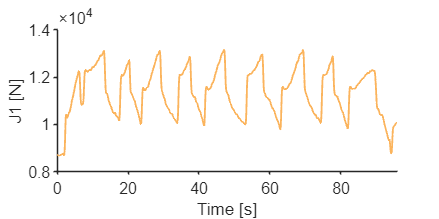

figure;
plot(Test.t, Test_real_down(:,1), 'LineWidth', 1, 'color', '#FBB45D');
set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim', [0, 96]);
set(gcf, 'unit', 'centimeters', 'position', [0 0 10 5]);
xlabel('Time [s]'); ylabel('J1 [N]');
drawnow update; shg; hold off;

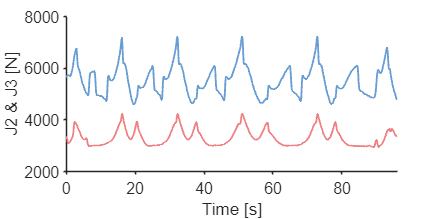


% 4.2 关节 2 与关节 3 参考力
figure;
plot(Test.t, Test_real_down(:,2), 'LineWidth', 1, 'color', '#699ED4'); hold on;
plot(Test.t, Test_real_down(:,3), 'LineWidth', 1, 'color', '#EF8183');
set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim', [0, 96]);
set(gcf, 'unit', 'centimeters', 'position', [0 0 10 5]);
xlabel('Time [s]'); ylabel('J2 & J3 [N]');
drawnow update; shg; hold off;

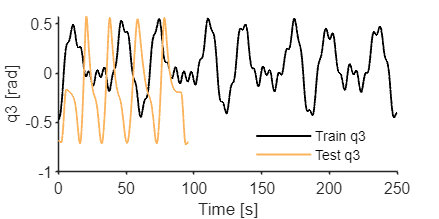


% 4.3 关节位置轨迹对比 (Train vs Test q3)
figure;
plot(Train.t, Train.q(:,3), 'LineWidth', 1, 'color', '#000000'); hold on;
plot(Test.t, Test.q(:,3), 'LineWidth', 1, 'color', '#fbb45d');
set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim', [0, 250]);
set(gcf, 'unit', 'centimeters', 'position', [0 0 10 5]);
xlabel('Time [s]'); ylabel('q3 [rad]');
legend({'Train q3', 'Test q3'}, 'Location', 'best', 'Box', 'off');
drawnow update; shg; hold off;

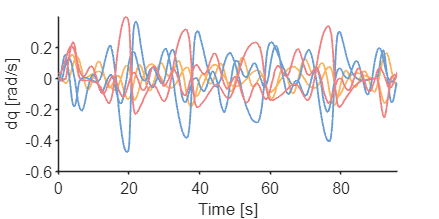


% 4.4 关节速度对比 (Train vs Test dq)
figure;
plot(Train.t, Train.dq(:,1), 'LineWidth', 1, 'color', '#fbb45d'); hold on;
plot(Test.t, Test.dq(:,1), 'LineWidth', 1, 'color', '#fbb45d');
plot(Train.t, Train.dq(:,2), 'LineWidth', 1, 'color', '#699ed4');
plot(Test.t, Test.dq(:,2), 'LineWidth', 1, 'color', '#699ed4');
plot(Train.t, Train.dq(:,3), 'LineWidth', 1, 'color', '#ef8183');
plot(Test.t, Test.dq(:,3), 'LineWidth', 1, 'color', '#ef8183');
set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim', [0, 96]);
set(gcf, 'unit', 'centimeters', 'position', [0 0 10 5]);
xlabel('Time [s]'); ylabel('dq [rad/s]');
drawnow update; shg; hold off;

## 4. 关节推力预测误差对比曲线 (时域均值误差曲线)

关节 1

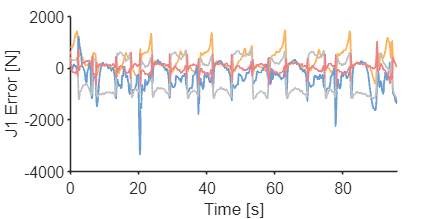

n = 1;
figure; % 神经网络模型对比
plot(Test.t, FFN_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#fbb45d'); hold on;
plot(Test.t, DeLaN_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#699ed4');
plot(Test.t, CAD_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#bfc0c2'); 
plot(Test.t, VDCDL_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#ef8183');
set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim', [0, 96]);
set(gcf, 'unit', 'centimeters', 'position', [0 0 10 5]);
xlabel('Time [s]'); ylabel('J1 Error [N]');
% legend({'FFN', 'DeLaN','CAD','VDCDL'}, 'Location', 'best', 'Box', 'off');
drawnow update; shg; hold off;

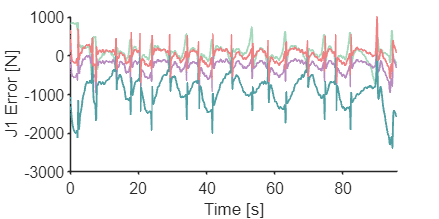


figure; % 物理/消融模型对比
plot(Test.t, SID_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#a4d9bb');hold on;
plot(Test.t, VDCDL_Fixed_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#b88cc0');
plot(Test.t, VDCDL_NoCADPrior_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#4F9FA3');
plot(Test.t, VDCDL_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#ef8183');
set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim', [0, 96]);
set(gcf, 'unit', 'centimeters', 'position', [0 0 10 5]);
xlabel('Time [s]'); ylabel('J1 Error [N]');
% legend({'SID', 'VDCDL-Fixed', 'VDCDL-NoCADPrior', 'VDCDL'}, 'Location', 'best', 'Box', 'off');
drawnow update; shg; hold off;

% 关节 2

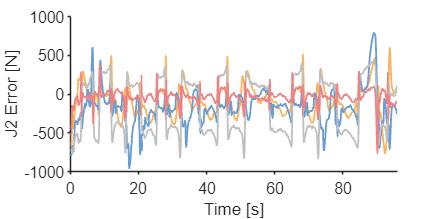

n = 2;
figure; % 神经网络模型对比
plot(Test.t, FFN_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#fbb45d'); hold on;
plot(Test.t, DeLaN_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#699ed4');
plot(Test.t, CAD_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#bfc0c2'); 
plot(Test.t, VDCDL_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#ef8183');
set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim', [0, 96]);
set(gcf, 'unit', 'centimeters', 'position', [0 0 10 5]);
xlabel('Time [s]'); ylabel('J2 Error [N]');
% legend({'FFN', 'DeLaN','CAD','VDCDL'}, 'Location', 'best', 'Box', 'off');
drawnow update; shg; hold off;

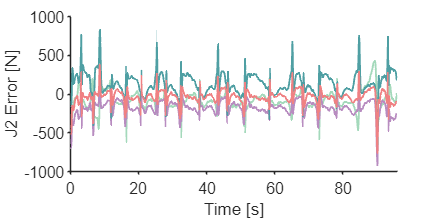


figure; % 物理/消融模型对比
plot(Test.t, SID_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#a4d9bb');hold on;
plot(Test.t, VDCDL_Fixed_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#b88cc0');
plot(Test.t, VDCDL_NoCADPrior_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#4F9FA3');
plot(Test.t, VDCDL_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#ef8183');
set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim', [0, 96]);
set(gcf, 'unit', 'centimeters', 'position', [0 0 10 5]);
xlabel('Time [s]'); ylabel('J2 Error [N]');
% legend({'SID', 'VDCDL-Fixed', 'VDCDL-NoCADPrior', 'VDCDL'}, 'Location', 'best', 'Box', 'off');
drawnow update; shg; hold off;

% 关节 3

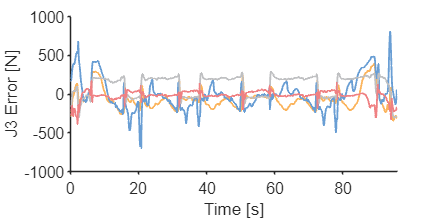

n = 3;
figure; % 神经网络模型对比
plot(Test.t, FFN_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#fbb45d'); hold on;
plot(Test.t, DeLaN_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#699ed4');
plot(Test.t, CAD_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#bfc0c2'); 
plot(Test.t, VDCDL_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#ef8183');
set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim', [0, 96]);
set(gcf, 'unit', 'centimeters', 'position', [0 0 10 5]);
xlabel('Time [s]'); ylabel('J3 Error [N]');
% legend({'FFN', 'DeLaN','CAD','VDCDL'}, 'Location', 'best', 'Box', 'off');
drawnow update; shg; hold off;

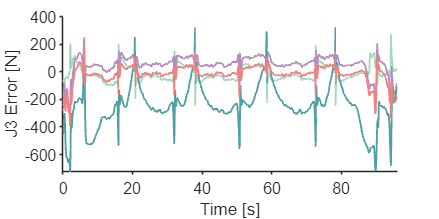


figure; % 物理/消融模型对比
plot(Test.t, SID_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#a4d9bb');hold on;
plot(Test.t, VDCDL_Fixed_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#b88cc0');
plot(Test.t, VDCDL_NoCADPrior_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#4F9FA3');
plot(Test.t, VDCDL_pred_down(:,n) - Test_real_down(:,n), 'LineWidth', 1, 'color', '#ef8183');
set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim', [0, 96]);
set(gcf, 'unit', 'centimeters', 'position', [0 0 10 5]);
xlabel('Time [s]'); ylabel('J3 Error [N]');
% legend({'SID', 'VDCDL-Fixed', 'VDCDL-NoCADPrior', 'VDCDL'}, 'Location', 'best', 'Box', 'off');
drawnow update; shg; hold off;

## 6. 各关节推力预测误差对比柱状图与误差棒 (MAE & RMSE [Mean ± Std])

% figure('Name', 'Test 3 (96s, Drawing) - Joint Error Distribution', 'Color', 'w');
% set(gcf, 'unit', 'centimeters', 'position', [2 2 18 14]);
% 
% joint_labels = {'Joint 1 (Boom)', 'Joint 2 (Arm)', 'Joint 3 (Bucket)'};
% 
% mae_means = [
%     mean(FFN_MAE_j, 1);
%     mean(DeLaN_MAE_j, 1);
%     CAD.MAE_joint;
%     SID.MAE_joint;
%     mean(VDCDL_Fixed_MAE_j, 1);
%     mean(VDCDL_NoCADPrior_MAE_j, 1);
%     mean(VDCDL_MAE_j, 1)
% ];
% 
% mae_stds = [
%     std(FFN_MAE_j, 0, 1);
%     std(DeLaN_MAE_j, 0, 1);
%     0, 0, 0;
%     0, 0, 0;
%     std(VDCDL_Fixed_MAE_j, 0, 1);
%     std(VDCDL_NoCADPrior_MAE_j, 0, 1);
%     std(VDCDL_MAE_j, 0, 1)
% ];
% 
% rmse_means = [
%     mean(FFN_RMSE_j, 1);
%     mean(DeLaN_RMSE_j, 1);
%     CAD.RMSE_joint;
%     SID.RMSE_joint;
%     mean(VDCDL_Fixed_RMSE_j, 1);
%     mean(VDCDL_NoCADPrior_RMSE_j, 1);
%     mean(VDCDL_RMSE_j, 1)
% ];
% 
% rmse_stds = [
%     std(FFN_RMSE_j, 0, 1);
%     std(DeLaN_RMSE_j, 0, 1);
%     0, 0, 0;
%     0, 0, 0;
%     std(VDCDL_Fixed_RMSE_j, 0, 1);
%     std(VDCDL_NoCADPrior_RMSE_j, 0, 1);
%     std(VDCDL_RMSE_j, 0, 1)
% ];
% 
% for k = 1:3
%     subplot(3, 1, k);
%     y_bar = [mae_means(:, k), rmse_means(:, k)];
%     err_bar = [mae_stds(:, k), rmse_stds(:, k)];
% 
%     b = bar(y_bar, 'grouped', 'BarWidth', 0.7);
%     b(1).FaceColor = [0.41, 0.62, 0.83]; % MAE (蓝)
%     b(2).FaceColor = [0.94, 0.51, 0.51]; % RMSE (红)
%     hold on;
% 
%     for m_idx = 1:size(y_bar, 2)
%         x_pos = b(m_idx).XEndPoints;
%         errorbar(x_pos, y_bar(:, m_idx), err_bar(:, m_idx), 'k', 'linestyle', 'none', ...
%                  'LineWidth', 1.0, 'CapSize', 6);
%     end
% 
%     set(gca, 'Box', 'off', 'TickDir', 'out', 'XTick', 1:7, 'XTickLabel', methods_name);
%     ylabel('Error [N]');
%     title(joint_labels{k}, 'FontWeight', 'bold');
%     if k == 1
%         legend({'MAE', 'RMSE'}, 'Location', 'northwest', 'Box', 'off');
%     end
%     grid on; set(gca, 'GridLineStyle', ':', 'GridAlpha', 0.4);
%     hold off;
% end
% drawnow update; shg;

## 7. 控制台汇总表格输出 (Mean ± Std)

fprintf('\n>>> 【Test 3 (96s 字符绘制) 误差统计汇总】各关节推力估计误差 (MAE / RMSE [N]) <<<\n');


>>> 【Test 3 (96s 字符绘制) 误差统计汇总】各关节推力估计误差 (MAE / RMSE [N]) <<<


T_Summary = table(methods_name', ...
    {sprintf('%.2f±%.2f / %.2f±%.2f', mean(FFN_MAE_j(:,1)), std(FFN_MAE_j(:,1)), mean(FFN_RMSE_j(:,1)), std(FFN_RMSE_j(:,1))); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(DeLaN_MAE_j(:,1)), std(DeLaN_MAE_j(:,1)), mean(DeLaN_RMSE_j(:,1)), std(DeLaN_RMSE_j(:,1))); ...
     sprintf('%.2f / %.2f', CAD.MAE_joint(1), CAD.RMSE_joint(1)); ...
     sprintf('%.2f / %.2f', SID.MAE_joint(1), SID.RMSE_joint(1)); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(VDCDL_Fixed_MAE_j(:,1)), std(VDCDL_Fixed_MAE_j(:,1)), mean(VDCDL_Fixed_RMSE_j(:,1)), std(VDCDL_Fixed_RMSE_j(:,1))); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(VDCDL_NoCADPrior_MAE_j(:,1)), std(VDCDL_NoCADPrior_MAE_j(:,1)), mean(VDCDL_NoCADPrior_RMSE_j(:,1)), std(VDCDL_NoCADPrior_RMSE_j(:,1))); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(VDCDL_MAE_j(:,1)), std(VDCDL_MAE_j(:,1)), mean(VDCDL_RMSE_j(:,1)), std(VDCDL_RMSE_j(:,1))) ;}, ...
    {sprintf('%.2f±%.2f / %.2f±%.2f', mean(FFN_MAE_j(:,2)), std(FFN_MAE_j(:,2)), mean(FFN_RMSE_j(:,2)), std(FFN_RMSE_j(:,2))); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(DeLaN_MAE_j(:,2)), std(DeLaN_MAE_j(:,2)), mean(DeLaN_RMSE_j(:,2)), std(DeLaN_RMSE_j(:,2))); ...
     sprintf('%.2f / %.2f', CAD.MAE_joint(2), CAD.RMSE_joint(2)); ...
     sprintf('%.2f / %.2f', SID.MAE_joint(2), SID.RMSE_joint(2)); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(VDCDL_Fixed_MAE_j(:,2)), std(VDCDL_Fixed_MAE_j(:,2)), mean(VDCDL_Fixed_RMSE_j(:,2)), std(VDCDL_Fixed_RMSE_j(:,2))); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(VDCDL_NoCADPrior_MAE_j(:,2)), std(VDCDL_NoCADPrior_MAE_j(:,2)), mean(VDCDL_NoCADPrior_RMSE_j(:,2)), std(VDCDL_NoCADPrior_RMSE_j(:,2))); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(VDCDL_MAE_j(:,2)), std(VDCDL_MAE_j(:,2)), mean(VDCDL_RMSE_j(:,2)), std(VDCDL_RMSE_j(:,2))) ;}, ...
    {sprintf('%.2f±%.2f / %.2f±%.2f', mean(FFN_MAE_j(:,3)), std(FFN_MAE_j(:,3)), mean(FFN_RMSE_j(:,3)), std(FFN_RMSE_j(:,3))); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(DeLaN_MAE_j(:,3)), std(DeLaN_MAE_j(:,3)), mean(DeLaN_RMSE_j(:,3)), std(DeLaN_RMSE_j(:,3))); ...
     sprintf('%.2f / %.2f', CAD.MAE_joint(3), CAD.RMSE_joint(3)); ...
     sprintf('%.2f / %.2f', SID.MAE_joint(3), SID.RMSE_joint(3)); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(VDCDL_Fixed_MAE_j(:,3)), std(VDCDL_Fixed_MAE_j(:,3)), mean(VDCDL_Fixed_RMSE_j(:,3)), std(VDCDL_Fixed_RMSE_j(:,3))); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(VDCDL_NoCADPrior_MAE_j(:,3)), std(VDCDL_NoCADPrior_MAE_j(:,3)), mean(VDCDL_NoCADPrior_RMSE_j(:,3)), std(VDCDL_NoCADPrior_RMSE_j(:,3))); ...
     sprintf('%.2f±%.2f / %.2f±%.2f', mean(VDCDL_MAE_j(:,3)), std(VDCDL_MAE_j(:,3)), mean(VDCDL_RMSE_j(:,3)), std(VDCDL_RMSE_j(:,3))) ;}, ...
    'VariableNames', {'Method', 'Joint1_MAE_RMSE', 'Joint2_MAE_RMSE', 'Joint3_MAE_RMSE'});
disp(T_Summary);

           Method                    Joint1_MAE_RMSE                     Joint2_MAE_RMSE                     Joint3_MAE_RMSE         
    ____________________    _________________________________    _______________________________    _________________________________

    {'FFN'             }    {'362.77±84.41 / 477.97±106.26' }    {'157.51±40.12 / 216.94±46.16'}    {'117.38±19.61 / 153.89±19.83'  }
    {'DeLaN'           }    {'365.49±60.58 / 548.77±68.78'  }    {'249.57±47.43 / 352.26±90.22'}    {'140.04±16.80 / 186.50±22.08'  }
    {'CAD'             }    {'664.52 / 738.97'              }    {'349.26 / 396.96'            }    {'155.72 / 174.58'              }
    {'SID'             }    {'174.17 / 242.52'              }    {'125.99 / 157.21'            }    {'48.42 / 56.98'                }
    {'VDCDL-Fixed'     }    {'276.09±0.15 / 323.18±0.34'    }    {'175.20±2.84 / 200.49±1.57'  }    {'77.85±3.14 / 89.02±4.87'      }
    {'VDCDL-NoCADPrior'}    {'458.05±374.20 / 523.64±382.35'}